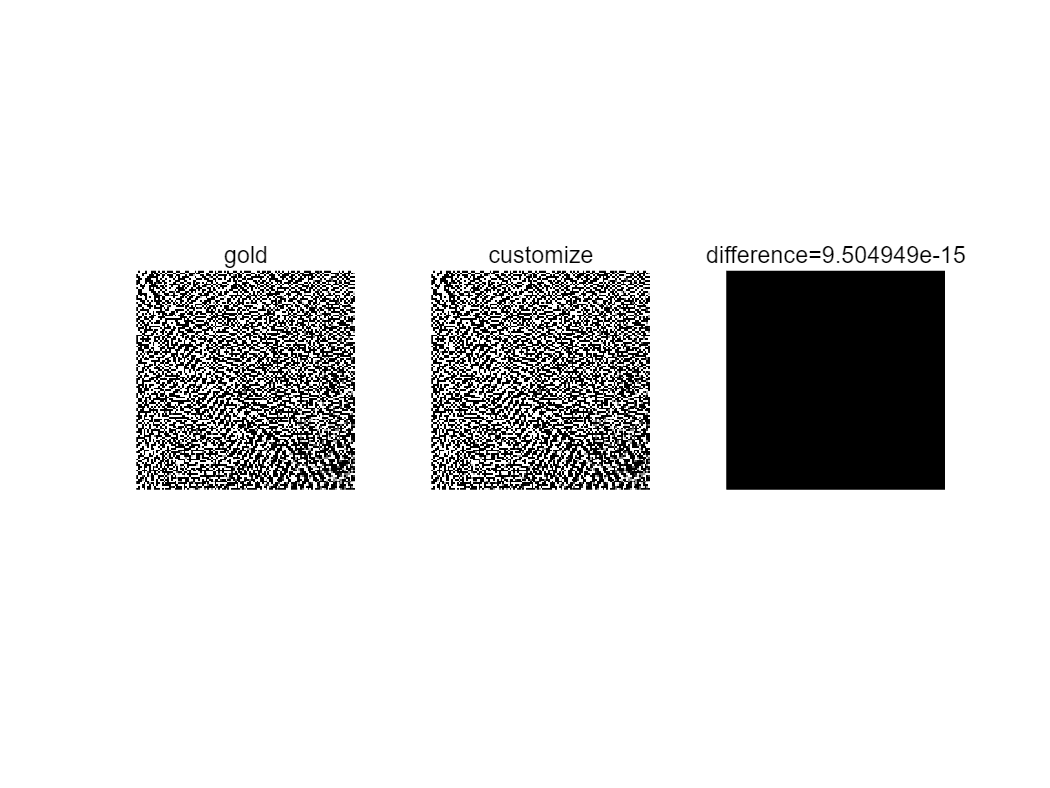

%Ch2_2.mlx
%compares customized DCT and proprietory DCT.
load JpegCoeff.mat;
load hall.mat;

sz=size(hall_gray);
X=sz(1);
Y=sz(2);
L=min(X,Y);

hall_gray=hall_gray(1:L,1:L);

gold=dct2(hall_gray);
customize=DCT(hall_gray);
diff=gold-customize;

    subplot(1,3,1);
    imshow(gold);
    title("gold");
    subplot(1,3,2);
    imshow(customize);
    title("customize");
    subplot(1,3,3);
    imshow(diff);
    title(sprintf("difference=%s",norm(gold-customize)/(L*L)));